# 1. Read Image & Identify Led Hubs


% -- CLEAR WORKSPACE --
clear; clc; close all;

% -- READ IMAGE --
img = imread('Image3.jpg');  % Adjust the file name/path as needed.

%% Set debug variable (set to true to mark failed hubs with dashed red)
DEBUG = true;

%% 1. Resize image if larger than 720x480
[origH, origW, ~] = size(img);
maxW = 720;
maxH = 480;
if origW > maxW || origH > maxH
    scale = min(maxW/origW, maxH/origH);
    img = imresize(img, scale);
    fprintf('Image resized from (%d, %d) to (%d, %d)\n', ...
        origH, origW, size(img,1), size(img,2));
end

Image resized from (3472, 4624) to (481, 640)


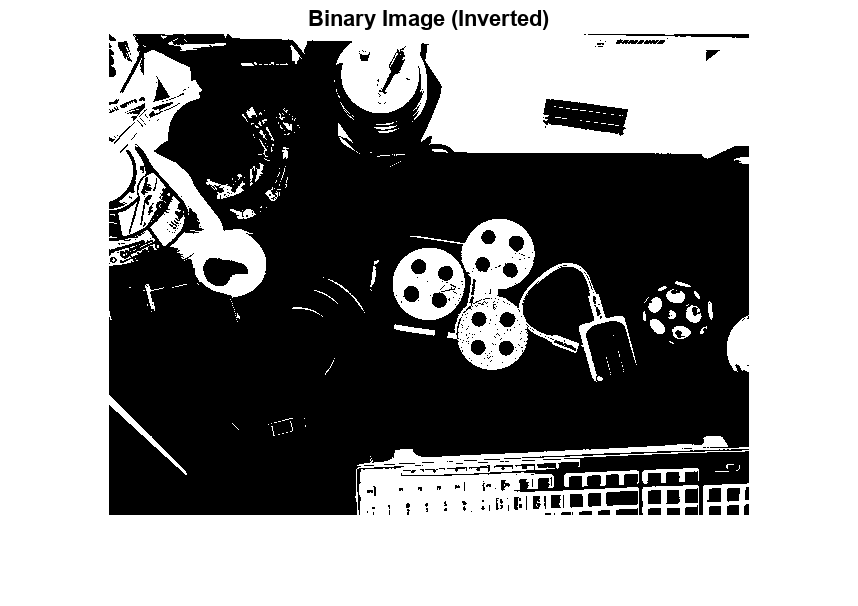


%% 2. Convert to grayscale and threshold
grayImg = rgb2gray(img);
level = 0.30;  % Manual threshold (tweak as needed)
binImg = imbinarize(grayImg, level);
binImg = ~binImg;  % Invert so that dark areas become white

figure; imshow(binImg);
title('Binary Image (Inverted)');

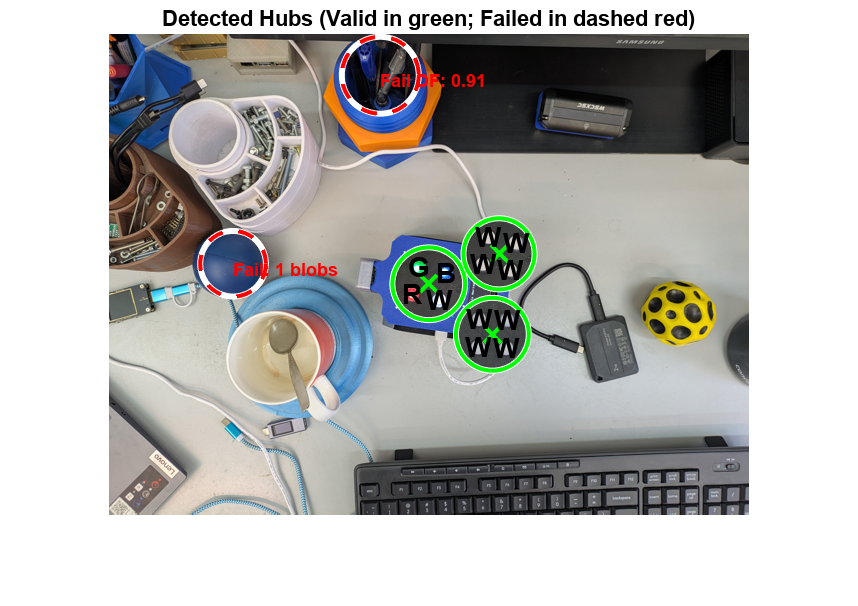

Valid Hub 1: Center=(320.3, 250.3), Radius=36.4, DarkFraction=0.80, 4 blobs detected.
Valid Hub 2: Center=(390.5, 220.3), Radius=35.5, DarkFraction=0.81, 4 blobs detected.
Valid Hub 3: Center=(383.9, 300.7), Radius=36.4, DarkFraction=0.76, 4 blobs detected.


Candidate hub at (124.6, 230.3) with radius=32.8 failed: 1 blobs detected (DarkFraction=0.74).


Circle 5 filtered out: DarkFraction=0.91



%% 3. Detect circles (candidate hubs) using imfindcircles
% The range [15 55] is an example; adjust as needed.
% 'ObjectPolarity','bright' because we inverted the image so that the hub appears bright.
[centers, radii, metric] = imfindcircles(binImg, [15 55], ...
    'ObjectPolarity','bright', 'Sensitivity',0.7);

%% 4. Prepare for drawing and initialize structure for valid hubs
figure; imshow(img); hold on;
title('Detected Hubs (Valid in green; Failed in dashed red)');

% Initialize structure to store valid hubs.
% Each valid hub will have:
%   hub.center, hub.radius, hub.numBlobs, hub.darkFraction,
%   hub.blob1.center, hub.blob1.color, ... up to blob4.
hubs = struct('center',{}, 'radius',{}, 'numBlobs',{}, 'darkFraction',{}, ...
    'blob1',{}, 'blob2',{}, 'blob3',{}, 'blob4',{});
validHubCount = 0;

%% 5. Process each candidate hub
for i = 1:length(radii)
    c = centers(i, :);  % Candidate hub center [x, y]
    r = radii(i);       % Candidate hub radius
    
    % Create a circular mask for this candidate hub.
    [X, Y] = meshgrid(1:size(binImg,2), 1:size(binImg,1));
    circleMask = ((X - c(1)).^2 + (Y - c(2)).^2) <= r^2;
    
    % Compute darkFraction: count white pixels in binImg (which represent dark areas originally)
    whiteCount = sum(binImg(circleMask), 'all');
    circleArea = sum(circleMask(:));
    darkFraction = whiteCount / circleArea;
    
    if darkFraction >= 0.70 && darkFraction <= 0.85
        % --- LED Blob Detection within the candidate hub ---
        % Force pixels outside the hub to white.
        hubSubImage = binImg;
        hubSubImage(~circleMask) = 1;
        
        % In the hub region, LED markers appear as black (0).
        blackRegion = (hubSubImage == 0);
        
        % Smooth the image to remove noise (morphological opening).
        se = strel('disk', 2);  % Adjust disk radius as needed.
        blackRegionSmooth = imopen(blackRegion, se);
        
        % Detect connected components (8-connected) in the smoothed image.
        CC = bwconncomp(blackRegionSmooth, 8);
        stats = regionprops(CC, 'Centroid', 'Area');
        
        % Set minimum blob area (in pixels); adjust if needed.
        minBlobArea = 50;
        validCentroids = [];
        validColors = {};  % To store the color of each blob.
        colorThreshold = 30;  % Threshold to decide if colors are similar (for white)
        
        % Process each detected blob.
        for j = 1:length(stats)
            if stats(j).Area >= minBlobArea
                % Save the centroid.
                validCentroids = [validCentroids; stats(j).Centroid]; %#ok<AGROW>
                
                % Retrieve the pixel indices for this blob.
                blobIndices = CC.PixelIdxList{j};
                
                % Compute the mean R, G, B values from the original color image.
                R_channel = img(:,:,1);
                G_channel = img(:,:,2);
                B_channel = img(:,:,3);
                meanR = mean(double(R_channel(blobIndices)));
                meanG = mean(double(G_channel(blobIndices)));
                meanB = mean(double(B_channel(blobIndices)));
                
                % Classify the blob color.
                if abs(meanR - meanG) < colorThreshold && abs(meanR - meanB) < colorThreshold && abs(meanG - meanB) < colorThreshold
                    blobColor = 'white';
                elseif meanR > meanG && meanR > meanB
                    blobColor = 'red';
                elseif meanG > meanR && meanG > meanB
                    blobColor = 'green';
                elseif meanB > meanR && meanB > meanG
                    blobColor = 'blue';
                else
                    blobColor = 'unknown';
                end
                
                validColors{end+1} = blobColor;  %#ok<AGROW>
            end
        end
        
        numBlobs = size(validCentroids, 1);
        
        % --- Hub Validation ---
        % We require exactly 4 LED markers (blobs) inside the hub.
        if numBlobs == 4
            % --- Sort the 4 blobs in clockwise order ---
            % Define "up" (negative y) as 0°.
            angles = zeros(numBlobs, 1);
            for k = 1:numBlobs
                dX = validCentroids(k,1) - c(1);
                dY = validCentroids(k,2) - c(2);
                % Angle relative to upward direction; use mod to get 0 to 2*pi.
                angles(k) = mod(atan2(dX, -dY), 2*pi);
            end
            [~, sortOrder] = sort(angles);
            sortedCentroids = validCentroids(sortOrder, :);
            sortedColors = validColors(sortOrder);
            
            % Store the valid hub in the structure.
            validHubCount = validHubCount + 1;
            hubs(validHubCount).center = c;
            hubs(validHubCount).radius = r;
            hubs(validHubCount).numBlobs = numBlobs;
            hubs(validHubCount).darkFraction = darkFraction;
            for k = 1:numBlobs
                fieldName = sprintf('blob%d', k);
                hubs(validHubCount).(fieldName).center = sortedCentroids(k, :);
                hubs(validHubCount).(fieldName).color = sortedColors{k};
            end
            
            % --- Draw Valid Hub ---
            % Draw a solid green circle around the hub.
            viscircles(c, r, 'Color', 'g');
            % Mark the hub center with a green X.
            plot(c(1), c(2), 'gx', 'MarkerSize', 12, 'LineWidth', 2);
            
            % For each blob, annotate its first letter (R, G, B, W).
            for k = 1:numBlobs
                blobLetter = upper(sortedColors{k}(1));  % Take the first letter and convert to uppercase.
                blobPos = sortedCentroids(k, :);
                text(blobPos(1), blobPos(2), blobLetter, 'Color', 'k', ...
                    'FontSize', 14, 'FontWeight', 'bold', 'HorizontalAlignment','center');
            end
            
            fprintf('Valid Hub %d: Center=(%.1f, %.1f), Radius=%.1f, DarkFraction=%.2f, 4 blobs detected.\n', ...
                validHubCount, c(1), c(2), r, darkFraction);
        else
            % Candidate hub passed darkFraction but does not have exactly 4 blobs.
            if DEBUG
                viscircles(c, r, 'Color', 'r', 'LineStyle', '--');
                text(c(1), c(2)+5, sprintf('Fail: %d blobs', numBlobs), ...
                    'Color', 'r', 'FontWeight', 'bold', 'FontSize', 9);
            end
            fprintf('Candidate hub at (%.1f, %.1f) with radius=%.1f failed: %d blobs detected (DarkFraction=%.2f).\n', ...
                c(1), c(2), r, numBlobs, darkFraction);
        end
    else
        % Candidate hub does not meet darkFraction criteria.
        if DEBUG
            viscircles(c, r, 'Color', 'r', 'LineStyle', '--');
            text(c(1), c(2)+5, sprintf('Fail DF: %.2f', darkFraction), ...
                'Color', 'r', 'FontWeight', 'bold', 'FontSize', 9);
        end
        fprintf('Circle %d filtered out: DarkFraction=%.2f\n', i, darkFraction);
    end
end


%% 6. (Optional) Display the structure of valid hubs
disp('Valid hubs detected:');

Valid hubs detected:


disp(hubs);

  1×3 struct array with fields:

    center
    radius
    numBlobs
    darkFraction
    blob1
    blob2
    blob3
    blob4

